# Quiz 4: Finding Features that Matter

load fisheriris.mat meas species

measV = var(meas)

measV =     0.6857    0.1900    3.1163    0.5810



measScaled = (meas - mean(meas))./range(meas);
measScaledV = var(measScaled)

measScaledV =     0.0529    0.0330    0.0895    0.1009


measScaledP = measScaledV/sum(measScaledV)

measScaledP =     0.1915    0.1194    0.3240    0.3651


[P,S,V] = pca(measScaled)

P =     0.4249    0.4232    0.7136   -0.3621
   -0.1507    0.9040   -0.3363    0.2168
    0.6163   -0.0604    0.0659    0.7824
    0.6457   -0.0098   -0.6110   -0.4578


S =    -0.6307    0.1076    0.0187   -0.0073
   -0.6229   -0.1043    0.0491   -0.0324
   -0.6695   -0.0514   -0.0196   -0.0074
   -0.6542   -0.1029   -0.0232    0.0201
   -0.6488    0.1335   -0.0151    0.0118
   -0.5353    0.2896   -0.0254    0.0003
   -0.6565    0.0107   -0.0918    0.0149
   -0.6258    0.0571    0.0140    0.0070
   -0.6756   -0.2007   -0.0360    0.0089
   -0.6456   -0.0672    0.0617    0.0090


V =     0.2325
    0.0325
    0.0096
    0.0018


VP = V/sum(V);
VPcum = cumsum(VP)

VPcum =     0.8414
    0.9589
    0.9936
    1.0000


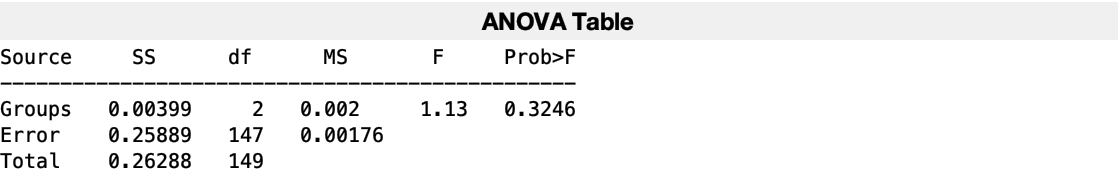

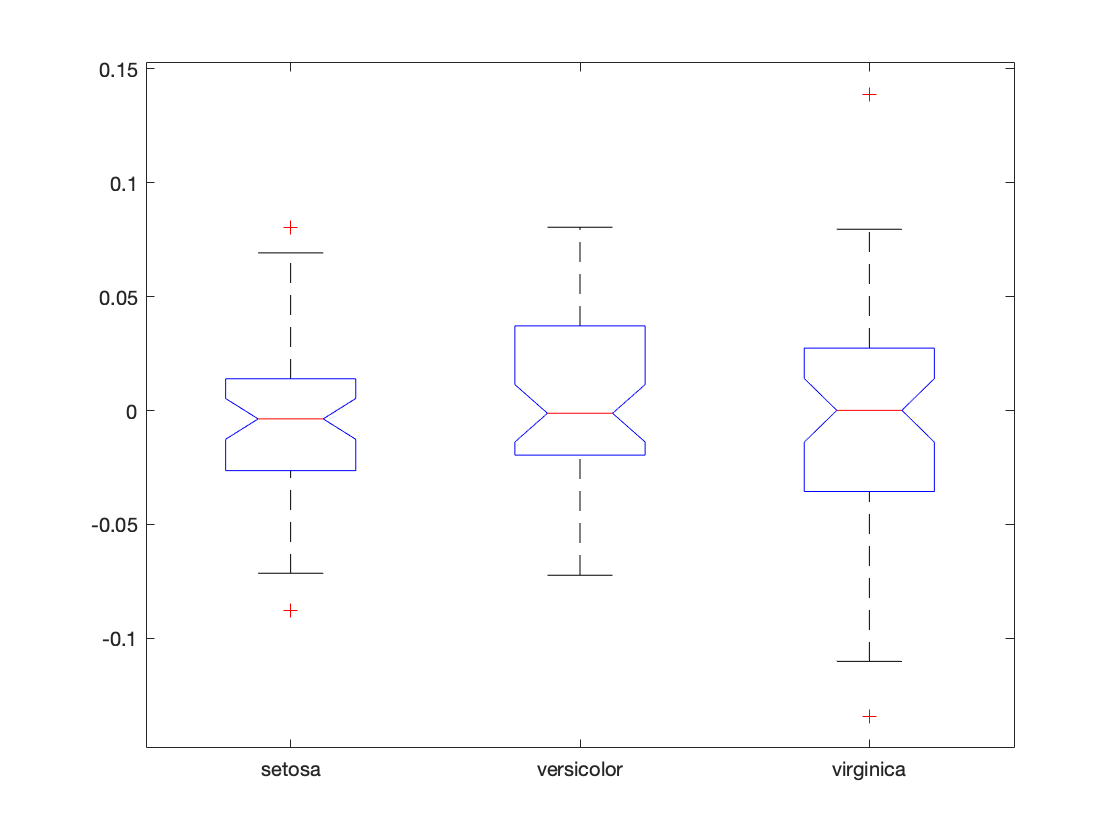

a = 0.3246

col = 4;
a = anova1(S(:,col),species)

reducedData = S(:, 1:2);

criterion = "DaviesBouldin";
eva = evalclusters(reducedData,"kmeans", criterion, "KList", 2:5)

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 150
         InspectedK: [2 3 4 5]
    CriterionValues: [0.4356 0.6091 0.6828 0.7403]
           OptimalK: 2


[clst,C] = kmeans(reducedData,3)

clst =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


C =     0.1510   -0.1225
   -0.6184    0.0686
    0.5567    0.1037


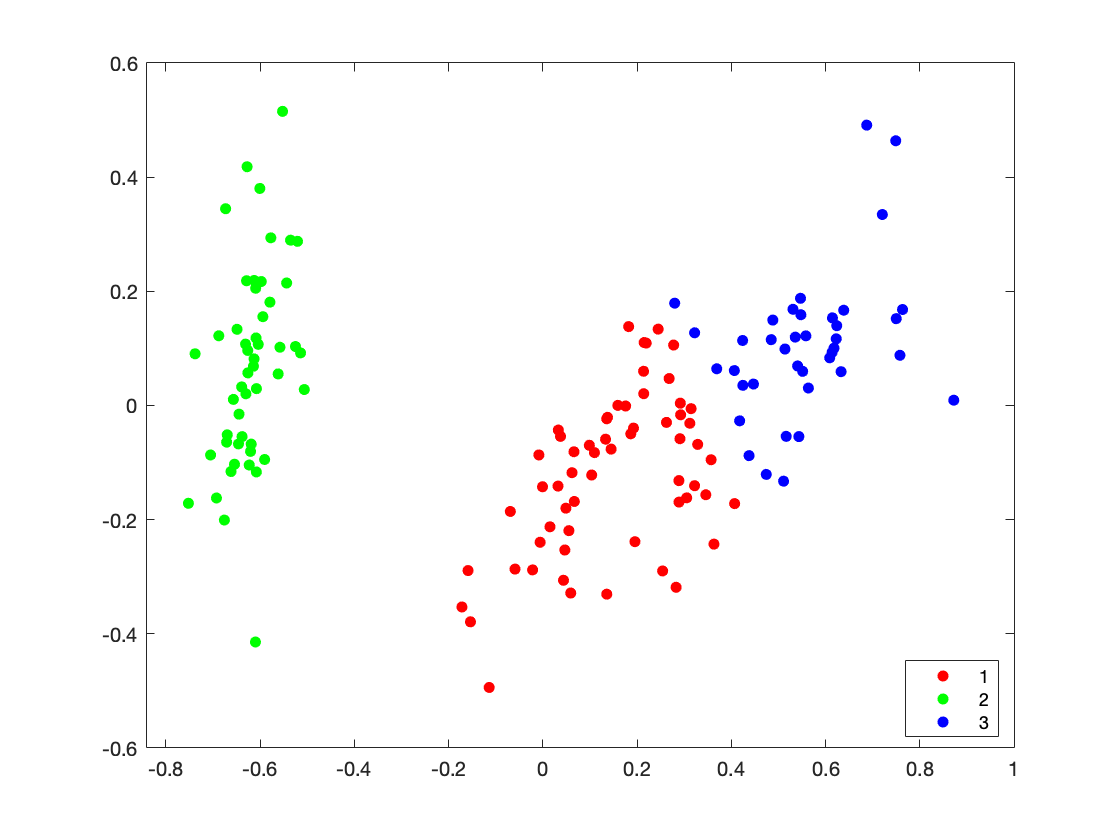


% Clustered data  clst is the output from kmeans
gscatter(reducedData(:,1), reducedData(:,2), clst)